close all
clear
clc

定义符号

syms t x n w

定义宽为10的连续时间矩形脉冲，计算其傅里叶变换

xt = heaviside(t)-heaviside(t-10);
Fx = fourier(xt);

生成频率采样点，计算这些点的频谱值

w1 = [-3*pi:0.02:3*pi];
Fx1 = double(subs(Fx,'w',w1));

定义宽为10的离散时间矩形脉冲，计算其z变换，并得到单位圆上的z变换，即DTFT

xn = heaviside(n) - heaviside(n-10);
Zxn = ztrans(xn);
DTFTx = subs(Zxn,'z',exp(1j*w));

得到其DTFT在频率采样点上的值

DTFTx1 = double(subs(DTFTx,'w',w1));

绘图

figure;
subplot(1,2,1), box on, hold on, grid on;

将连续时间矩形脉冲傅里叶变换“盘”在单位圆上，注意w1范围是6pi，所以盘了三圈

plot3(cos(w1),sin(w1),real(Fx1));
zlabel('F(x)','FontSize',14);
set(gca,'FontSize',14);
set(gca,'XLim',[-1.5,1.5],'YLim',[-1.5,1.5]);
view(69,18);
subplot(1,2,2), box on, hold on, grid on;

同理绘制离散时间矩形脉冲的DTFT，注意同样盘了三圈，但因为周期性，所以重合在一起

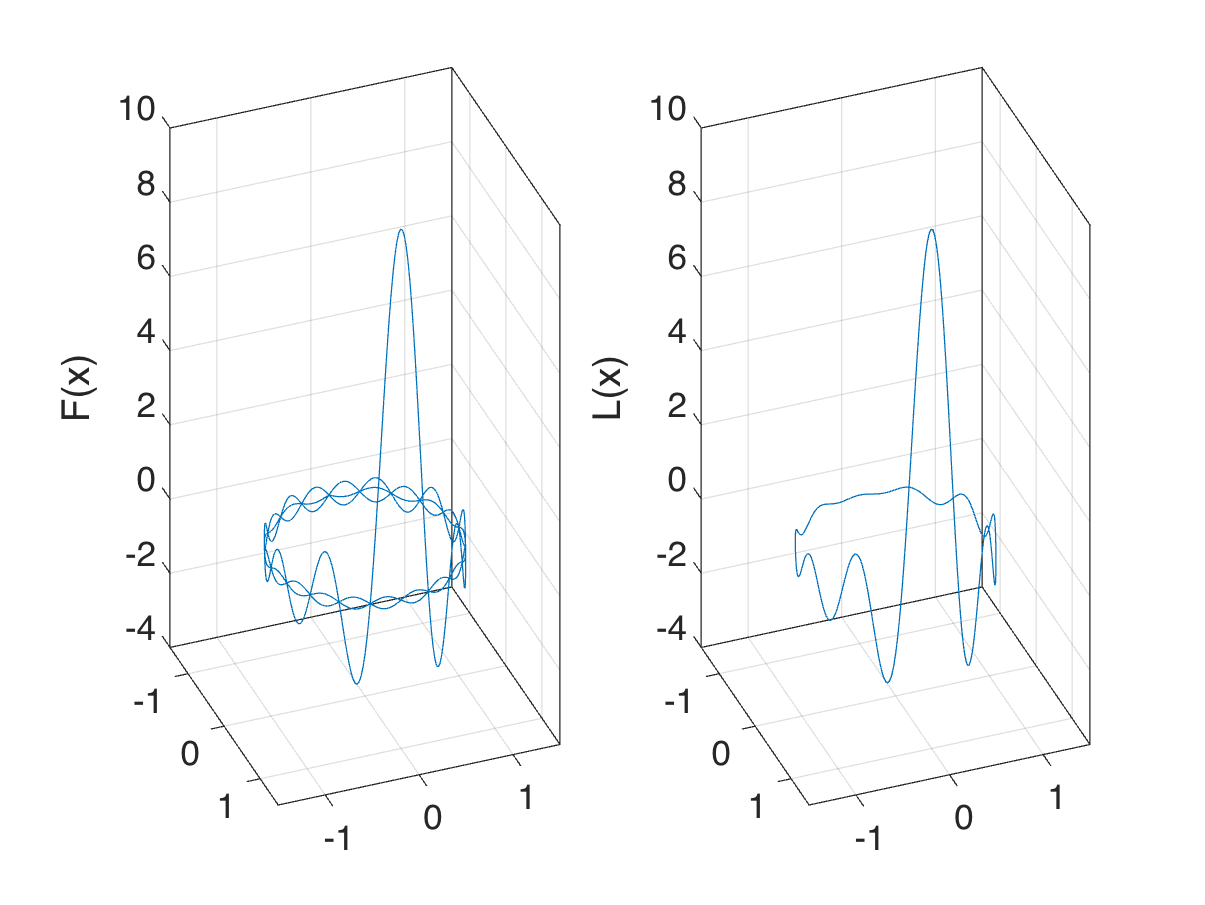

plot3(cos(w1),sin(w1),real(DTFTx1));
zlabel('L(x)','FontSize',14);
set(gca,'FontSize',14);
set(gca,'XLim',[-1.5,1.5],'YLim',[-1.5,1.5]);
view(69,18);